### Parameters

clc;
clear all;
close all;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('SIM_AI');

Adding matlab path to: D:\code\SIM_AI


Parameters

Wireless packet type: SC


T_coh = 0.0142

T =      1     4     9    16    25    36    49    64    81   100   121   144   169   196   225   256   289   324   361   400   441   484   529   576   625


SNR_dB = 28.2642

### 3GPP Channel settings

%% --- CDL channel object (TR 38.901) --------------------------------------
cdl = nrCDLChannel;
cdl.DelayProfile         = profile;          % NLOS: CDL-A/B/C, LOS: CDL-D/E LOS (§7.7.1)
cdl.DelaySpread          = DS_ns*1e-9;       % set RMS-DS via scaling (Eq. 7.7-1 in §7.7.3)
cdl.CarrierFrequency     = fc;
cdl.SampleRate           = fs;
cdl.MaximumDopplerShift  = maxDoppler;

#### Transmitter

% Attach the antenna elements to the CDL
cdl.TransmitAntennaArray = txArray;


#### Receiver

cdl.ReceiveAntennaArray = rxArray;


Orient the transmit and receive antenna arrays to point at each other by using the LOS path angles returned in the characteristic information.

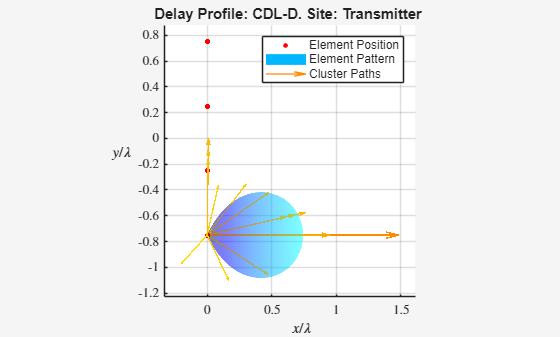

cdlInfo = cdl.info;
cdl.TransmitArrayOrientation = [cdlInfo.AnglesAoD(1) cdlInfo.AnglesZoD(1)-90 0]';
cdl.ReceiveArrayOrientation = [cdlInfo.AnglesAoA(1) cdlInfo.AnglesZoA(1)-90 0]';

figure; displayChannel(cdl,'LinkEnd','Tx');
view(0,90)

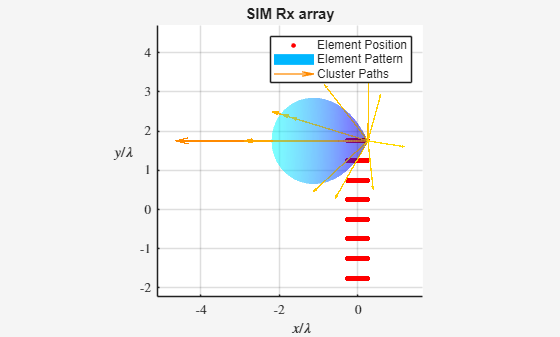

figure; displayChannel(cdl,'LinkEnd','Rx'); title('SIM Rx array');
view(0,90)

#### **Waveform generation**

**Description: **All 4 antennas transmit the same Wi-Fi waveform, which is stored in the variable txWaveform of dimensions time x patch. Each column is the signal received at **one patch** of your SIM.

cdlInfo = info(cdl);
Nt = cdlInfo.NumInputSignals;   % should be as follows from the number of patches according to the MU array
psdu = randi([0 1],cfgDMG_loc.PSDULength*8,1); 
tx = wlanWaveformGenerator(psdu,cfgDMG_loc);
txWaveform = repmat(tx, 1, Nt);    % Nsamp × 4
size(txWaveform)

ans =         5440           4


#### CDL channel

% communication distance between MU and SIM (meters)
MU_Pos=[SIM_Pos(1) SIM_Pos(2) h_MU]

MU_Pos =     5.0000    2.5000    1.0000


d_comm = norm(MU_Pos - SIM_Pos);
%Pathloss model for indoor factory according to Table 7.4.1-1 pp. 29 in [1]
PL_dB=31.84+21.5*log10(d_comm)+19*log10(fc/1e9);
%free-space formula
% PL_dB=20*log10(4*pi*d_comm*fc/physconst('LightSpeed'));
% link budget
scale = sqrt( (10^((Ptx_dBm + Gtx_dBi + Grx_dBi - PL_dB)/10)) / 1000 );
%CDL received signal
[rxWaveform, pathGains] = cdl(txWaveform);
%Denormalized signal
rxWaveform = rxWaveform * scale;

#### signal per SIM patch

% sig_k = rxWaveform(:, k);


#### Power across SIM (N×N)

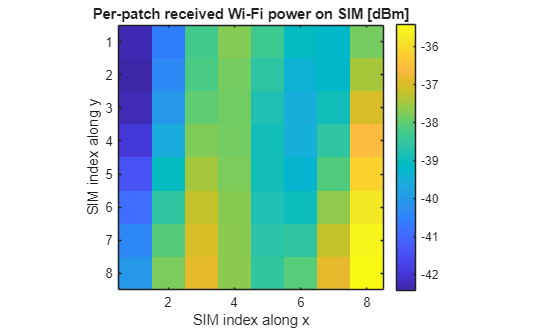

% Average power per patch (linear)
perPatchPower = mean(abs(rxWaveform).^2, 1);   % 1 x Nr
powerGrid_lin = reshape(perPatchPower, [N_y N_x]);   % [row=y, col=x]
% Avoid log of zero
powerGrid_lin(powerGrid_lin == 0) = eps;

% Convert to dB, normalized to max = 0 dB
powerGrid_dBm = 10*log10(powerGrid_lin/1e-3);
% powerGrid_dB = powerGrid_dB - max(powerGrid_dB(:));   % normalize

% Plot
figure;
imagesc(powerGrid_dBm);
axis image;
colorbar;
xlabel('SIM index along x');
ylabel('SIM index along y');
title('Per-patch received Wi-Fi power on SIM [dBm]');


% Optional: limit dynamic range to, say, -40…0 dB
% caxis([-40 0]);

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end



% Map ArrayNormal string to rotation that sends +x (canonical boresight)
% to the desired global axis.
function Rn = arrayNormalRot(nstr)
    switch lower(nstr)
        case 'x'
            Rn = eye(3);
        case '-x'
            Rn = roty(180);      % +x -> -x
        case 'y'
            Rn = rotz(90);       % +x -> +y
        case '-y'
            Rn = rotz(-90);      % +x -> -y
        case 'z'
            Rn = roty(90);       % +x -> +z
        case '-z'
            Rn = roty(-90);      % +x -> -z
        otherwise
            error('Unsupported ArrayNormal: %s', nstr);
    end
end


### References

[1] "Study on channel model for frequencies from 0.5 to 100 GHz (Release 16)," 3GPP, TR 38.901 V16.1.0, Nov. 2020.  

[2] [https://ch.mathworks.com/help/releases/R2025a/5g/ug/visualize-cdl-channel-model-characteriscticsl.html](https://ch.mathworks.com/help/releases/R2025a/5g/ug/visualize-cdl-channel-model-characteriscticsl.html) 

[4] WLAN PPDU Structure, [https://de.mathworks.com/help/wlan/gs/dmg-ppdu-structure.html](https://de.mathworks.com/help/wlan/gs/dmg-ppdu-structure.html)